# compare stellar mass and ssfr plots of mock observation and actrual observations

global DEFAULT_MATFILE_DIR
global simDisplayName
catName=[DEFAULT_MATFILE_DIR '/ssfr0_stellarMass_radProfiles_projected_yangSamplePoint_fiber_' simDisplayName];
load(catName);
obscatFib=ssfrMassProfs;
clear ssfrMassProfs

catName=[DEFAULT_MATFILE_DIR '/ssfr0_stellarMass_radProfiles_projected_yangSamplePoint_' simDisplayName];
load(catName);
obscat=ssfrMassProfs;
clear ssfrMassProfs

fname3d=[DEFAULT_MATFILE_DIR '/ssfr0_stellarMass_radProfiles_' simDisplayName];

load(fname3d);
prof3d=profStruct;

clear profStruct;


% massTag={'$M_\mathrm{h}=10^{11}-10^{12}\,\mathrm{M_\odot}$',...
%     '$M_\mathrm{h}=10^{12}-10^{13}\,\mathrm{M_\odot}$',...
%     '$M_\mathrm{h}=10^{13}-10^{14}\,\mathrm{M_\odot}$',...
%     '$M_\mathrm{h}=10^{14}-10^{15}\,\mathrm{M_\odot}$'};
massTag={'11-12','12-13','13-14','14-15'};

colors=brewermap(8,'Set1');

## compare profiles generated with mean and median averaging in profiles

do this with and without fiber effects separately 

## stellar mass

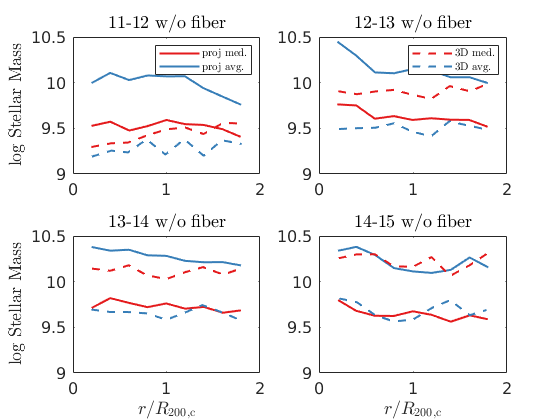


% without fiber 
figure('color','w');


for k=1:4 % loop over host mass bins
    subplot(2,2,k)
    h=[];
    xmed=obscat.rposMed(:,k)';
    xmedPol=[xmed fliplr(xmed)];
    
    xavg=obscat.rposAvg(:,k)';
    xavgPol=[xavg fliplr(xavg)];
    
    
    ymed=log10(obscat.smassMedMed(3,:,k));
    
    ymedPol=[log10(obscat.smassMedMed(2,:,k)) ...
        fliplr(log10(obscat.smassMedMed(4,:,k)))];
    
    
    yavg=log10(obscat.smassAvgMed(3,:,k));
    
    yavgPol=[log10(obscat.smassAvgMed(2,:,k)) ...
        fliplr(log10(obscat.smassAvgMed(4,:,k)))];
    
    x3med=prof3d.starMass(k).xMean;
    y3med=log10(prof3d.starMass(k).yMean);
    
    x3avg=prof3d.starMass(k).xMedian;
    y3avg=log10(prof3d.starMass(k).yMedian);
    
    
    %fill(xmedPol,ymedPol,colors(k,:),'facealpha',0.2,'edgecolor','none')
    
    h(end+1)=plot(xmed,ymed,'-','color',colors(1,:),'linewidth',1.5,...
        'DisplayName',['proj med.']);
    hold on
    %fill(xavgPol,yavgPol,colors(k,:),'facealpha',0.2,'edgecolor','none')
    hold on
    h(end+1)=plot(xavg,yavg,'-','color',colors(2,:),'linewidth',1.5,...
        'DisplayName',['proj avg.']);
    
    h(end+1)=plot(x3med,y3med,'--','color',colors(1,:),'linewidth',1.5,...
        'DisplayName',['3D med. ']);
    
    h(end+1)=plot(x3avg,y3avg,'--','color',colors(2,:),'linewidth',1.5,...
        'DisplayName',['3D avg. ']);
    
    if k==1
        hl=legend(h(1:2),'Interpreter','latex','fontsize',8,'location','northeast','numcolumns',1);
    end
    if k==2
        hl=legend(h(3:4),'Interpreter','latex','fontsize',8,'location','northeast','numcolumns',1);
    end
    xlim([0 2])
    ylim([9 10.5])
    
    set(gca,'fontsize',12,'box','on')
    
    if k==3 || k==4
        xlabelmine('$r/R_\mathrm{200,c}$');
    end
    if k==1 || k==3
        ylabelmine('log Stellar Mass');
    end
    titlemine([massTag{k} ' w/o fiber']);
    
end

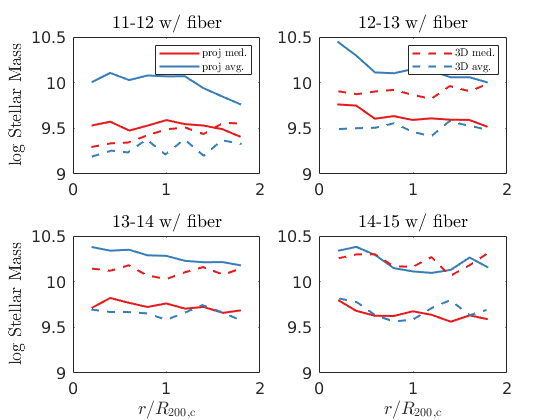



% with fiber 

% without fiber 
figure('color','w');


for k=1:4 % loop over host mass bins
    subplot(2,2,k)
    h=[];
    xmed=obscatFib.rposMed(:,k)'; 
    xavg=obscatFib.rposAvg(:,k)';
    
    ymed=log10(obscatFib.smassMedMed(3,:,k));
    yavg=log10(obscatFib.smassAvgMed(3,:,k));
        
    x3med=prof3d.starMass(k).xMean;
    y3med=log10(prof3d.starMass(k).yMean);
    
    x3avg=prof3d.starMass(k).xMedian;
    y3avg=log10(prof3d.starMass(k).yMedian);
    
    
    %fill(xmedPol,ymedPol,colors(k,:),'facealpha',0.2,'edgecolor','none')
    
    h(end+1)=plot(xmed,ymed,'-','color',colors(1,:),'linewidth',1.5,...
        'DisplayName',['proj med.']);
    hold on
    %fill(xavgPol,yavgPol,colors(k,:),'facealpha',0.2,'edgecolor','none')
    hold on
    h(end+1)=plot(xavg,yavg,'-','color',colors(2,:),'linewidth',1.5,...
        'DisplayName',['proj avg.']);
    
    h(end+1)=plot(x3med,y3med,'--','color',colors(1,:),'linewidth',1.5,...
        'DisplayName',['3D med. ']);
    
    h(end+1)=plot(x3avg,y3avg,'--','color',colors(2,:),'linewidth',1.5,...
        'DisplayName',['3D avg. ']);
    
    if k==1
        hl=legend(h(1:2),'Interpreter','latex','fontsize',8,'location','northeast','numcolumns',1);
    end
    if k==2
        hl=legend(h(3:4),'Interpreter','latex','fontsize',8,'location','northeast','numcolumns',1);
    end
    xlim([0 2])
    ylim([9 10.5])
    
    set(gca,'fontsize',12,'box','on')
    
    if k==3 || k==4
        xlabelmine('$r/R_\mathrm{200,c}$');
    end
    if k==1 || k==3
        ylabelmine('log Stellar Mass');
    end
    titlemine([massTag{k} ' w/ fiber']);
    
end

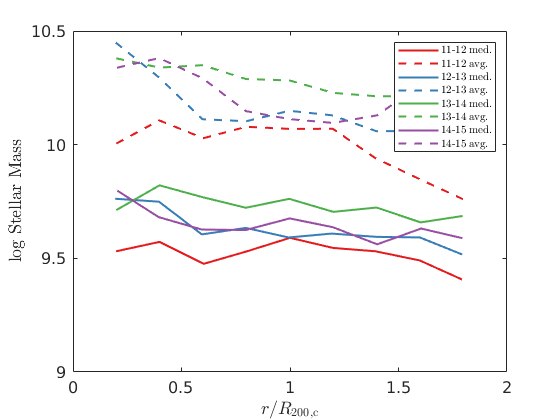






%% plot together 


figure('color','w');

 h=[];
for k=1:4 % loop over host mass bins
    
   
    xmed=obscatFib.rposMed(:,k)'; 
    xavg=obscatFib.rposAvg(:,k)';
    
    ymed=log10(obscatFib.smassMedMed(3,:,k));
    yavg=log10(obscatFib.smassAvgMed(3,:,k));
        
    x3med=prof3d.starMass(k).xMean;
    y3med=log10(prof3d.starMass(k).yMean);
    
    x3avg=prof3d.starMass(k).xMedian;
    y3avg=log10(prof3d.starMass(k).yMedian);
    
    
    %fill(xmedPol,ymedPol,colors(k,:),'facealpha',0.2,'edgecolor','none')
    
    h(end+1)=plot(xmed,ymed,'-','color',colors(k,:),'linewidth',1.5,...
        'DisplayName',[massTag{k} ' med.']);
    hold on
    %fill(xavgPol,yavgPol,colors(k,:),'facealpha',0.2,'edgecolor','none')
    hold on
    h(end+1)=plot(xavg,yavg,'--','color',colors(k,:),'linewidth',1.5,...
        'DisplayName',[massTag{k} ' avg.']);
    
%     h(end+1)=plot(x3med,y3med,'--','color',colors(1,:),'linewidth',1.5,...
%         'DisplayName',['3D med. ']);
%     
%     h(end+1)=plot(x3avg,y3avg,'--','color',colors(2,:),'linewidth',1.5,...
%         'DisplayName',['3D avg. ']);
%     
end
        hl=legend(h,'Interpreter','latex','fontsize',8,'location','northeast','numcolumns',1);
   
    xlim([0 2])
    ylim([9 10.5])
    
    set(gca,'fontsize',12,'box','on')
    
   
        xlabelmine('$r/R_\mathrm{200,c}$');
        ylabelmine('log Stellar Mass');

## compare profiles with and without fiber effect

do this for mean and medain averaging separately 

## compare profilers to observations